# C Code Generation for a MATLAB Kalman Filtering Algorithm

This example shows how to generate C code for a MATLAB Kalman filter function, `kalmanfilter`, which estimates the position of a moving object based on past noisy measurements. It also shows how to generate a MEX function for this MATLAB code to increase the execution speed of the algorithm in MATLAB.

## Prerequisites

There are no prerequisites for this example.

## About the `kalmanfilter` Function

The `kalmanfilter` function predicts the position of a moving object based on its past values. It uses a Kalman filter estimator, a recursive adaptive filter that estimates the state of a dynamic system from a series of noisy measurements. Kalman filtering has a broad range of application in areas such as signal and image processing, control design, and computational finance.

## About the Kalman Filter Estimator Algorithm

The Kalman estimator computes the position vector by computing and updating the Kalman state vector. The state vector is defined as a 6-by-1 column vector that includes position (x and y), velocity (Vx Vy), and acceleration (Ax and Ay) measurements in a 2-dimensional Cartesian space. Based on the classical laws of motion:


$$\left\{ \begin{array}{rcl}
            X & = & X_0 + V_x dt    \\
            Y & = & Y_0 + V_y dt    \\
          V_x & = & V_{x0} + A_x dt \\
          V_y & = & V_{y0} + A_y dt \\
         \end{array} \right.
$$


The iterative formula capturing these laws are reflected in the Kalman state transition matrix "A". Note that by writing about 10 lines of MATLAB code, you can implement the Kalman estimator based on the theoretical mathematical formula found in many adaptive filtering textbooks.

type kalmanfilter.m

%   Copyright 2010 The MathWorks, Inc.
function y = kalmanfilter(z) 
%#codegen
dt=1;
% Initialize state transition matrix
A=[ 1 0 dt 0 0 0;...     % [x  ]            
       0 1 0 dt 0 0;...     % [y  ]
       0 0 1 0 dt 0;...     % [Vx]
       0 0 0 1 0 dt;...     % [Vy]
       0 0 0 0 1 0 ;...     % [Ax]
       0 0 0 0 0 1 ];       % [Ay]
H = [ 1 0 0 0 0 0; 0 1 0 0 0 0 ];    % Initialize measurement matrix
Q = eye(6);
R = 1000 * eye(2);
persistent x_est p_est                % Initial state conditions
if isempty(x_est)
    x_est = zeros(6, 1);           % x_est=[x,y,Vx,Vy,Ax,Ay]'
    p_est = zeros(6, 6);
end
x_est(1)=58.201413/100;
x_est(2)=-48.354115/100;

% Predicted state and covariance
x_prd = A * x_est;
p_prd = A * p_est * A' + Q;
% Estimation
S = H * p_prd' * H' + R;
B = H * p_prd';
klm_gain = (S \ B)';
% Estimated state and covariance
x_est = x_prd + klm_gain * (z - H * x_prd);
p_est = p_prd - klm_gain * H * p_prd;
% Compute the estimated measurements
y = H * x_est;
end        

## Load Test Data

The position of the object to track are recorded as x and y coordinates in a Cartesian space in a MAT file called `position_data.mat`. The following code loads the MAT file and plots the trace of the positions. The test data includes two sudden shifts or discontinuities in position which are used to check that the Kalman filter can quickly re-adjust and track the object.

load position_data.mat
hold; grid;

Current plot held


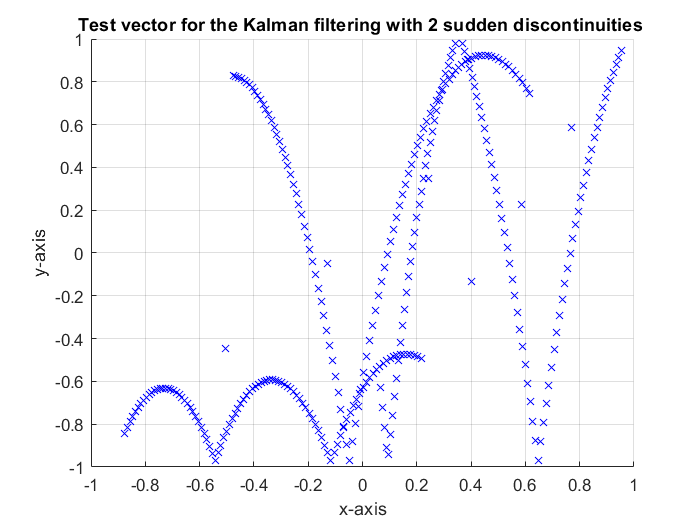

Current plot released


for idx = 1: numPts
z = position(:,idx);
plot(z(1), z(2), 'bx');
axis([-1 1 -1 1]);
end
title('Test vector for the Kalman filtering with 2 sudden discontinuities ');
xlabel('x-axis');ylabel('y-axis');
hold;

## Inspect and Run the `ObjTrack` Function

The `ObjTrack.m` function calls the Kalman filter algorithm and plots the trajectory of the object in blue and the Kalman filter estimated position in green. Initially, you see that it takes a short time for the estimated position to converge with the actual position of the object. Then, three sudden shifts in position occur. Each time the Kalman filter readjusts and tracks the object after a few iterations.

type ObjTrack

%   Copyright 2010 The MathWorks, Inc.
function ObjTrack(position)
%#codegen
% First, setup the figure

numPts = length(position);               % Process and plot 300 samples
figure;hold;grid;            % Prepare plot window
% Main loop
for idx = 1: numPts
    z = position(:,idx);     % Get the input data
    y = kalmanfilter(z);        % Call Kalman filter to estimate the position
    plot_trajectory(z,y);    % Plot the results
end
hold;
end   % of the function


Current plot held


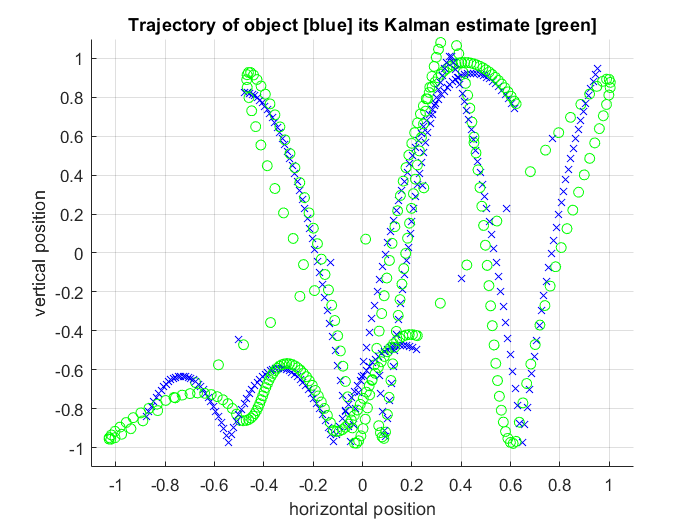

Current plot released


ObjTrack(position)

## Generate C Code

The `codegen` command with the `-config:lib` option generates C code packaged as a standalone C library.

Because C uses static typing, `codegen` must determine the properties of all variables in the MATLAB files at compile time. Here, the `-args` command-line option supplies an example input so that `codegen` can infer new types based on the input types. 

The `-report` option generates a compilation report that contains a summary of the compilation results and links to generated files. After compiling the MATLAB code, `codegen` provides a hyperlink to this report.

z = position(:,1);
codegen  -config:lib -report -c kalmanfilter.m -args {z}


Simulink startup was interrupted. To ensure that Simulink is ready
 to use, run sl_refresh_customizations before opening a model.

Program interruption (Ctrl-C) has been detected.
Use help codegen for more information on using this command.


Error using codegen

## Inspect the Generated Code

The generated C code is in the `codegen/lib/kalmanfilter/` folder. The files are:

dir codegen/lib/kalmanfilter/

## Inspect the C Code for the `kalmanfilter.c` Function

type codegen/lib/kalmanfilter/kalmanfilter.c

## Accelerate the Execution Speed of the MATLAB Algorithm

You can accelerate the execution speed of the `kalmanfilter` function that is processing a large data set by using the `codegen` command to generate a MEX function from the MATLAB code.

## Call the `kalman_loop` Function to Process Large Data Sets

First, run the Kalman algorithm with a large number of data samples in MATLAB. The `kalman_loop` function runs the `kalmanfilter` function in a loop. The number of loop iterations is equal to the second dimension of the input to the function.

type kalman_loop

## Baseline Execution Speed Without Compilation

Now time the MATLAB algorithm. Use the `randn` command to generate random numbers and create the input matrix `position` composed of 100,000 samples of (2x1) position vectors. Remove all MEX files from the current folder. Use the MATLAB stopwatch timer (`tic` and `toc` commands) to measure how long it takes to process these samples when running the `kalman_loop` function.

clear mex
delete(['*.' mexext])
position = randn(2,100000);
tic, kalman_loop(position); a=toc;

## Generate a MEX Function for Testing

Next, generate a MEX function using the command `codegen` followed by the name of the MATLAB function `kalman_loop`. The `codegen` command generates a MEX function called `kalman_loop_mex`. You can then compare the execution speed of this MEX function with that of the original MATLAB algorithm.

codegen -args {position} kalman_loop.m
which kalman_loop_mex

## Time the MEX Function

Now, time the MEX function `kalman_loop_mex`. Use the same signal `position` as before as the input, to ensure a fair comparison of the execution speed. 

tic, kalman_loop_mex(position); b=toc;

## Comparison of the Execution Speeds

Notice the speed execution difference using a generated MEX function.

display(sprintf('The speedup is %.1f times using the generated MEX over the baseline MATLAB function.',a/b));

*Copyright 2018 The MathWorks, Inc.*